% matrixstruct = struct('name',[],'matrix',[])
% matrixstruct.name = 'Haming74';
% matrixstruct.matrix = [1 1 1; 1 1 0; 1 0 1; 0 1 1; 1 0 0; 0 1 0; 0 0 1;]';
% matrixstruct(2).name = 'ExHaming84';
% matrixstruct(2).matrix = [1 1 1 1; 1 1 0 1; 1 0 1 1; 0 1 1 1; 1 0 0 1; 0 1 0 1; 0 0 1 1; 0 0 0 1]';
% matrixstruct(3).name = 'Haming1511';
% matrixstruct(3).matrix = [1 1 1 1; 1 1 1 0; 1 1 0 1;1 1 0 0; 1 0 1 1 ;1 0 0 1;1 0 1 0; 0 1 1 1; 0 1 1 0; 0 1 0 1; 0 0 1 1 ; 1 0 0 0 ; 0 1 0 0; 0 0 1 0;0 0 0 1]';
% matrixstruct(4).name = 'Linear63';
% matrixstruct(4).matrix = [1 1 1;1 1 0 ;1 0 1; 0 1 1 ;1 0 0; 0 1 0;]';
% matrixstruct(5).name = 'Linear52';
% matrixstruct(5).matrix = []

%  A = [1 1 1; 1 1 0; 1 0 1; 0 1 1; 1 0 0; 0 1 0; 0 0 1;]';
% %  buff1 = horzcat(buff1,A(:,safepat));
%  v = [1 2 3 4]
% s = [1 2]

A = [1 0 1 1 0 1 0;1 1 1 0 1 1 1;1 0 0 1 1 1 1;0 1 0 1 0 0 1;1 1 1 0 1 0 0;0 1 1 1 1 1 0;]

A =      1     0     1     1     0     1     0
     1     1     1     0     1     1     1
     1     0     0     1     1     1     1
     0     1     0     1     0     0     1
     1     1     1     0     1     0     0
     0     1     1     1     1     1     0


gfrank(A)

ans = 6

B = [1 0 1 1 0 1 0;0 1 0 1 1 0 1;1 1 1 0 1 1 0;1 1 1 1 0 1 1;1 0 1 0 0 1 1;0 1 0 1 1 1 0;1 1 0 1 1 0 1]

B =      1     0     1     1     0     1     0
     0     1     0     1     1     0     1
     1     1     1     0     1     1     0
     1     1     1     1     0     1     1
     1     0     1     0     0     1     1
     0     1     0     1     1     1     0
     1     1     0     1     1     0     1


gfrank(B)

ans = 7

%  matrixstruct(6).name = 'Rank7';
%  matrixstruct(6).matrix = B
T = [0 0 0 0 0 0 1]'

T =      0
     0
     0
     0
     0
     0
     1


b = A * T

b =      0
     1
     1
     1
     0
     0


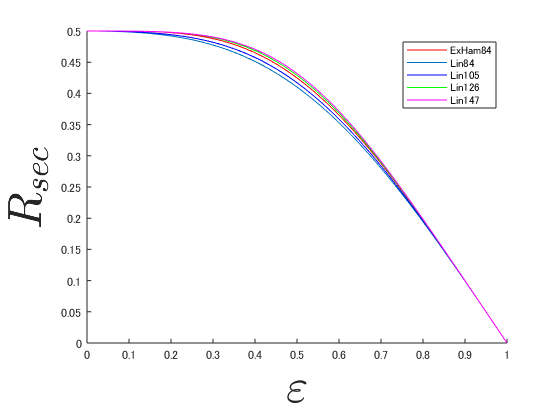

% mod(b,2)
%２つのグラフの差を塗るよう
% distance = trapz(0.01,plotDataTable.ExHaming84)
 hold on
 xlabel('$$\varepsilon$$','Interpreter','Latex','FontSize',36);
 ylabel('$$R_{sec}$$','Interpreter', 'Latex','FontSize',36);
 plot(plotDataTable{:,1},plotDataTable{:,3},'r-');
  plot(plotDataTable{:,1},plotDataTable{:,14},'-');
 plot(plotDataTable{:,1},plotDataTable{:,11},'b-');
 plot(plotDataTable{:,1},plotDataTable{:,12},'g-');
 plot(plotDataTable{:,1},plotDataTable{:,13},'m-');
  legend('ExHam84','Lin84','Lin105','Lin126','Lin147')
 hold off

% buff = zeros(101,1);
% for i = 1:101
%     buff(i,1) = (3/7);
% end
% plot(plotDataTable{:,1},buff,'r-');
% plot(plotDataTable{:,1},plotDataTable{:,7},'g-')
%  plot(plotDataTable{:,1},theoreticalvalue{:,2},'-');
%  x = table2array(plotDataTable(:,1));
%  y2 = table2array(theoreticalvalue(:,2))
%  y1 = table2array(plotDataTable(:,2))
%  ar = area(x,[y1 y2-y1])
%  set(ar(1),'FaceColor','None')
